SimpleBacktestV1

clear
tic

T = readtable("Trend Trading Input Output Data.xlsx", "Sheet","Price Data");


PriceTTraw = table2timetable (T) ;

PriceTTSemiClean = fillmissing (PriceTTraw, "previous") ;
PriceTT = fillmissing (PriceTTSemiClean, "next")

PriceTT = 2859×665 timetable
       Time         ANTM     ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN     AISA     AIMS     AHAP     AGRS     AGRO     AGII    AGAR    ADRO    ADMG    ADMF     ADHI     ADES     ACST     ACES    ABMM     ABDA     ABBA    AALI     AMAG     ALTO     ALMI    ALKA     ALDO     AKSI    AKRA    AKPI     AKKU     DLTA</

%SMA Signal
LeadDays = 2 ; 
LagDays = 20 ;

SMALead = movavg (PriceTT, 'simple', LeadDays) ;
SMALag = movavg (PriceTT, 'simple', LagDays) ;

SMASignalTT = PriceTT ;
SMASignalTT.Variables = SMALead.Variables > SMALag.Variables ;
SMASignalFinalTT = SMASignalTT ;
SMASignalFinal = SMASignalFinalTT.Variables ;
SMASignal = SMASignalTT.Variables ;
SMASignalFinal (2:end, :) = SMASignal (1:end-1, :)

SMASignalFinal =      0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     1     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     0     1     1     1     1  

SMASignalFinal (1, :) = 0

SMASignalFinal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     1     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     0     1     1     1     1  

SMASignalFinalTT.Variables = SMASignalFinal

SMASignalFinalTT = 2859×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS    AHAP    AGRS    AGRO    AGII    AGAR    ADRO    ADMG    ADMF    ADHI    ADES    ACST    ACES    ABMM    ABDA    ABBA    AALI    AMAG    ALTO    ALMI    ALKA    ALDO    AKSI    AKRA    AKPI    AKKU    DLTA    <


%Strategy
TradingCosts = [0.2/100, 0.2/100] ;

buyCost = -TradingCosts(1) ;
sellCost = -TradingCosts(2) ;

TradingCostTT = SMASignalTT ;
TradingCosthelper = TradingCostTT.Variables ;
TradingCostTTVar = TradingCosthelper

TradingCostTTVar =      0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     1     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     0     1     0     1     1     1     1     1     1     1     1     0     0     1     0     1     0     1     1     1     0     1     1     0     1     1     0     1     1     1     1     0     1
     1     0     0     1     0     0     0     0     0     0     0     0     1

TradingCostTTVar(2:end,:) = TradingCosthelper (2:end, :) - TradingCosthelper (1:end-1, :) ;
TradingCostTTVar (TradingCostTTVar == 1) = buyCost;
TradingCostTTVar (TradingCostTTVar == -1) = sellCost;


%CapAlloc

SumDailySignal = sum(SMASignalFinalTT.Variables, 2) ;
DailyAlloc = 1 ./ SumDailySignal ;
DailyAlloc (DailyAlloc == inf) = 0 ;

AllocbySym = SMASignalFinalTT.Variables .* DailyAlloc ;

retperSymRawVar = tick2ret (PriceTT);

retperSymNet = SMASignalFinalTT;
SMASignalFinalTTVar = SMASignalFinalTT.Variables ;
retperSymNetVar = retperSymNet.Variables ;
retperSymNetVar (2:end, :) = ((retperSymRawVar.Variables .* SMASignalFinalTTVar (2:end, :)) + ...
    TradingCostTTVar(2:end, :)) .* AllocbySym(2:end, :) ;

retperSymNet.Variables = retperSymNetVar

retperSymNet = 2859×665 timetable
       Time           ANTM           ANJT           ANDI           AMRT           AMOR           AMIN           AMFG           AMAR        AMAN       AISA           AIMS           AHAP           AGRS           AGRO           AGII           AGAR           ADRO        ADMG       ADMF           ADHI           ADES           ACST           ACES           ABMM           ABDA           ABBA           AALI           AMAG        ALTO       ALMI



% DailyPortRet
DailyPortRetVar = sum(retperSymNetVar ,2) ;
DailyPortRetVar  (1,:) = 0 ;
DailyPortRet = timetable (PriceTT.Time, DailyPortRetVar, 'variablenames', "dailyRet") ;
cumRet = ret2tick (DailyPortRet )

cumRet = 2859×1 timetable
       Time        dailyRet
    ___________    ________

    04-Jan-2010          1 
    05-Jan-2010     1.0012 
    06-Jan-2010     1.0017 
    07-Jan-2010    0.99871 
    08-Jan-2010     1.0063 
    11-Jan-2010     1.0124 
    12-Jan-2010     1.0217 
    13-Jan-2010     1.0163 
    14-Jan-2010     1.0218 
    15-Jan-2010     1.0206 
    18-Jan-2010     1.0137 
    19-Jan-2010     1.0178 
    20-Jan-2010     1.0161 
    21-Jan-2010      1.015 
    22-Jan-2010     1.0142 
    25-Jan-2010     1.0153 


cumRetVar = cumRet.Variables 

cumRetVar =     1.0000
    1.0012
    1.0017
    0.9987
    1.0063
    1.0124
    1.0217
    1.0163
    1.0218
    1.0206


cumRetVar(end,:)

ans = 0.3143

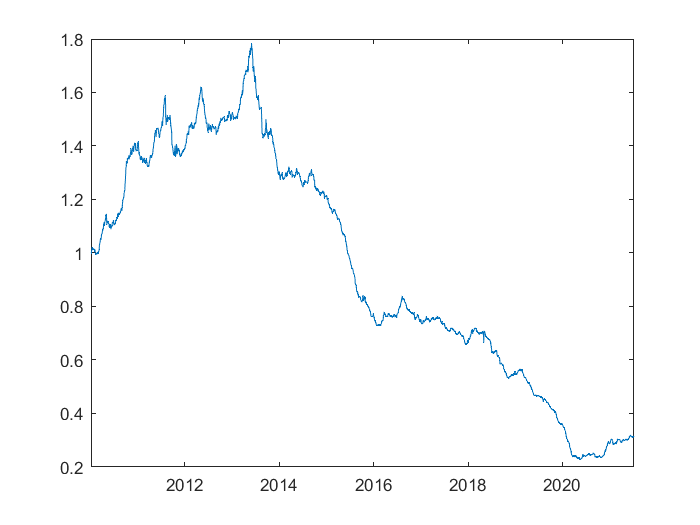

plot (cumRet.Time, cumRet.dailyRet)

retperSymNetVar (isinf(retperSymNetVar))


ans =

  0×1 empty double column vector



max (DailyAlloc )

ans = 0.0476

max(DailyPortRetVar)

ans = 0.0660

toc

Elapsed time is 22.248285 seconds.
